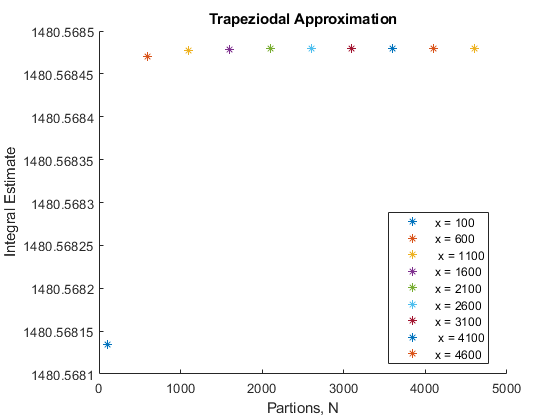

clear
clc
%setting up constants
figure 
hold on
N = 100 : 500 : 5000;
%get area and plot
for n = N
    area = TRAPsolver(n);
    scatter(n, area, "*")
end
%aesthetics
title("Trapeziodal Approximation")
xlabel("Partions, N")
ylabel("Integral Estimate")
legend("x = 100", "x = 600", " x = 1100", "x = 1600", "x = 2100", "x = 2600",...
    "x = 3100", " x = 4100", "x = 4600", "location", "best")

function area = TRAPsolver(n)
    dx = 1/n;
    %initialize x
    x = 0 : dx : 30;
    %assign val
    values = 200.*(x./(5 + x)).*(exp((-2.*x)./30));
    area = 0;
    %get area
    for i = 2 : length(values)
        area = area + (dx/2)*(values(i) + values(i - 1));
    end
end

Integral Approximate: 1480.57 units^2 (actual estimate is ~1480.56865 but due to rounding, the true estimate seems higher than it is).